%% Bordsfyrverkeri – Projekt A i numo25
% Simulering av en liten rakets rörelse i två faser:
% 1. Med dragkraft (0 ≤ t ≤ 0.08)
% 2. Fri rörelse utan dragkraft (t > 0.08)

clear all; close all; clf;

%% STARTVÄRDEN OCH PARAMETRAR
v_yx = 21;                      % Startfart (m/s)
teta = deg2rad(81);            % Startvinkel (radianer)
h = 0.01;                      % Steglängd
F = 1;                         % Kraft under brinntid
t1 = 0; t2 = 0.08;             % Start/sluttid för brinntid
tend = 4;                      % Simuleringens sluttid

%% LÖS DIFFEKTIONSYSTEM MED TRE STEGLÄNGDER
[z1, z2, z3, t_vals1, t_vals2, t_vals3, Error] = Rocketman(t1, t2, tend, h, F, v_yx, 1);

%% BERÄKNA VINKEL VERSUS TID (i grader)
graderVektor = getdegvec(t_vals1, h, z1);

%% EXTRAHERA FEL OCH ORDNING
ord1 = Error(2,4); ord2 = Error(3,4);
delta11 = Error(2,2); delta12 = Error(3,2);  % Del 1
delta21 = Error(2,3); delta22 = Error(3,3);  % Del 2

fprintf('Ordningnr1 = %.4f\n', ord1);

Ordningnr1 = 16.0435


fprintf('Ordningnr2 = %.4f\n', ord2);

Ordningnr2 = 16.1309


fprintf('Felet första halvering (del 1) = %.13f\n', delta11);

Felet första halvering (del 1) = 0.0000000000705


fprintf('Felet andra halvering (del 1) = %.13f\n', delta12);

Felet andra halvering (del 1) = 0.0000000000044


fprintf('Felet första halvering (del 2) = %.13f\n', delta21);

Felet första halvering (del 2) = 0.0000000000727


fprintf('Felet andra halvering (del 2) = %.13f\n', delta22);

Felet andra halvering (del 2) = 0.0000000000045


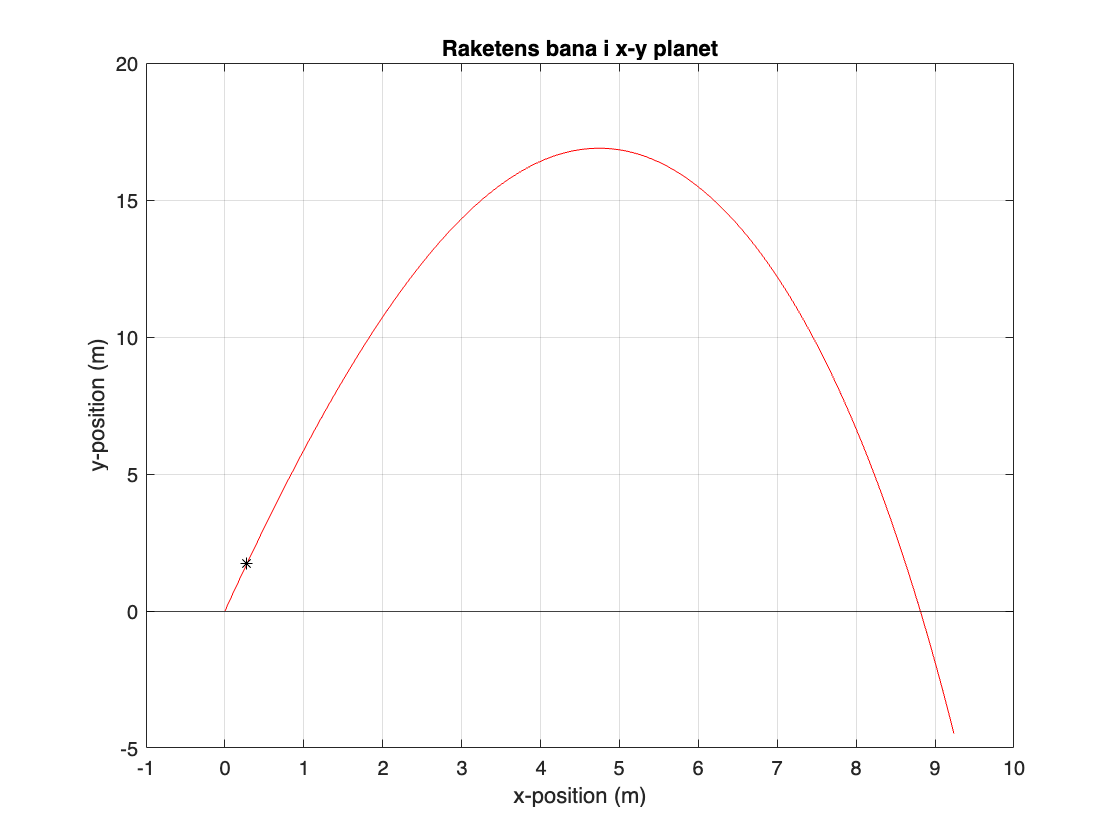


%% PLOTT RAKETENS BANA
figure;
plot(z1(1,:), z1(2,:), 'b'); hold on;
plot(z2(1,:), z2(2,:), 'g');
plot(z3(1,:), z3(2,:), 'r');
plot(z3(1,34), z3(2,34), '*-k');
xlim([-1,10]); ylim([-5,20]);
yline(0,'-k');
xlabel('x-position (m)');
ylabel('y-position (m)');
title('Raketens bana i x-y planet');
grid on;



%% ---------------------------------------------------------
%% FUNKTION: Rocketman – LÖSER PROBLEMET I TVÅ FASER
function [z1,z2,z3,t_vals1,t_vals2,t_vals3,Error] = Rocketman(t1,t2,tend,h,F,v_yx,nr1)

    teta = 81 * (pi/180);
    x0 = 0; y0 = 0;
    halvering = [1,2,4];
    steg = zeros(3,1);
    [xv, yv] = velocity(v_yx, teta);  % Startkomponenter

    % Fas 1: Med dragkraft
    for i = 1:3
        hi = h / halvering(i);
        steg(i) = hi;
        [zd11, t_vals11] = RungeKutta(t1, t2, 0, hi, F, x0, y0, xv, yv);
        zpart1{i} = zd11;
        tpart1{i} = t_vals11;
    end

    [E1, pp1] = error_calc(zpart1, nr1);
    initial = zpart1{3};  % Bästa uppskattning

    % Fas 2: Efter brinntid, utan kraft
    for j = 1:3
        hj = h / halvering(j);
        [zd21, t_vals21] = RungeKutta(t2, tend, 0, hj, 0, ...
            initial(1,end), initial(2,end), initial(3,end), initial(4,end));
        zpart2{j} = zd21;
        tpart2{j} = t_vals21;
    end

    [E2, pp2] = error_calc(zpart2, nr1);

    ordning = zeros(3,1);
    ordning(2) = pp1;
    ordning(3) = pp2;

    % Kombinera faserna till tre lösningar
    z1 = [zpart1{1}, zpart2{1}(:,2:end)];
    z2 = [zpart1{2}, zpart2{2}(:,2:end)];
    z3 = [zpart1{3}, zpart2{3}(:,2:end)];

    t_vals1 = [tpart1{1}, tpart2{1}(2:end)];
    t_vals2 = [tpart1{2}, tpart2{2}(2:end)];
    t_vals3 = [tpart1{3}, tpart2{3}(2:end)];

    Error = [steg, E1, E2, ordning];
end

%% ---------------------------------------------------------
%% FUNKTION: error_calc – BERÄKNAR FEL OCH ORDNING
function [E, pp] = error_calc(zz, nr)
    z11 = zz{1}; z22 = zz{2}; z33 = zz{3};
    E = zeros(3,1);
    pp = (z11(nr,end)-z22(nr,end))/(z22(nr,end)-z33(nr,end));
    E(2) = z22(nr,end) - z11(nr,end);
    E(3) = z33(nr,end) - z22(nr,end);
end

%% ---------------------------------------------------------
%% FUNKTION: RungeKutta – FYRKORDS RK-LÖSNING
function [z_val, t_vals] = RungeKutta(a,b,N,h,v,x0,y0,xdot0,ydot0)
    t_vals = a:h:b;
    N = length(t_vals);
    z = zeros(4,N);
    z(:,1) = [x0; y0; xdot0; ydot0];

    for i = 1:N-1
        t = t_vals(i);
        z_i = z(:,i);
        k1 = funcsolve(t, z_i, v);
        k2 = funcsolve(t + h/2 , z_i + (h/2)*k1, v);
        k3 = funcsolve(t + h/2 , z_i + (h/2)*k2, v);
        k4 = funcsolve(t + h , z_i + h*k3, v);
        z(:,i+1) = z_i + (k1 + 2*k2 + 2*k3 + k4)*(h/6);
    end

    z_val = z;
end

%% ---------------------------------------------------------
%% FUNKTION: velocity – BERÄKNAR HASTIGHETSKOMPONENTER
function [xvl, yvl] = velocity(vxy, teta)
    xvl = vxy * cos(teta);
    yvl = vxy * sin(teta);
end

%% ---------------------------------------------------------
%% FUNKTION: M – MASSA SOM FUNKTION AV TID
function mass = M(m0, t)
    if t <= 0.08
        mass = m0 - 0.08 * t;
    else
        mass = m0 - 0.08 * 0.08;
    end
end

%% ---------------------------------------------------------
%% FUNKTION: F_lyft – KRAFT SOM FUNKTION AV TID
function force = F_lyft(t, s)
    if t <= 0.08
        force = s;
    else
        force = 0;
    end
end

%% ---------------------------------------------------------
%% FUNKTION: anglecal – BERÄKNAR RAKETENS VINKEL
function phi = anglecal(t, vvx, vvy)
    if t <= 0
        phi = deg2rad(81);
    else
        phi = atan(vvy / vvx);
    end
end

%% ---------------------------------------------------------
%% FUNKTION: getdegvec – RETURNERAR VINKLAR I GRADER
function degrevector = getdegvec(tvalue, h, hasv)
    deg = zeros(1, length(tvalue));
    for i = 1:length(tvalue)
        deg(i) = 180 * anglecal(tvalue(i), hasv(3,i), hasv(4,i)) / pi;
    end
    degrevector = deg;
end

%% ---------------------------------------------------------
%% FUNKTION: funcsolve – DEFINIERAR SYSTEMETS DERIVATOR
function dzdt = funcsolve(t, z, v)
    x = z(1); y = z(2);
    x_dot = z(3); y_dot = z(4);
    g = 9.82;
    m0 = 0.05;
    k_x = 0.001; k_y = 0.001;

    V = sqrt(x_dot^2 + y_dot^2);
    phi = anglecal(t, x_dot, y_dot);
    m = M(m0, t);

    dzdt = zeros(4,1);
    dzdt(1) = x_dot;
    dzdt(2) = y_dot;
    dzdt(3) = (F_lyft(t, v)*cos(phi) - k_x * x_dot * V) / m;
    dzdt(4) = (F_lyft(t, v)*sin(phi) - k_y * y_dot * V) / m - g;
end

